# Tarea Nº1: Profesor Laboret

Se tiene para cada alumno en un archivo adjunto (PDF) una función de transferencia con polos p1 y p2, probablemente un cero y una ganancia K, además especificaciones de sobrepaso, tiempo de respuesta 2%, y período de muestreo.

## Función de transferencia a lazo abierto

Según el archivo PDF, al alumno Villar se le asigna la siguiente función de transferencia:

G = zpk([],[-2 -3],10)

G =
 
      10
  -----------
  (s+2) (s+3)
 
Continuous-time zero/pole/gain model.



Además, se especifica el período de muestreo siguiente:

Tm = 0.12;

Ahora, se obtiene la función de transferencia de lazo abierto $G_D \left(s\right)$ del sistema de la figura con un retentor de orden cero a la entrada y con el período de muestreo anteriormente asignado, de forma que en diagrama de bloques se tenga algo como la figura adjunta a continuación.

Gd = c2d(G,Tm, 'zoh')

Gd =
 
   0.059115 (z+0.8187)
  ---------------------
  (z-0.7866) (z-0.6977)
 
Sample time: 0.12 seconds
Discrete-time zero/pole/gain model.



Una vez discretizado el sistema mediante el uso de un retentor de orden cero, se procede a obtener los diagramas de polos y ceros para cada uno de los sistemas.

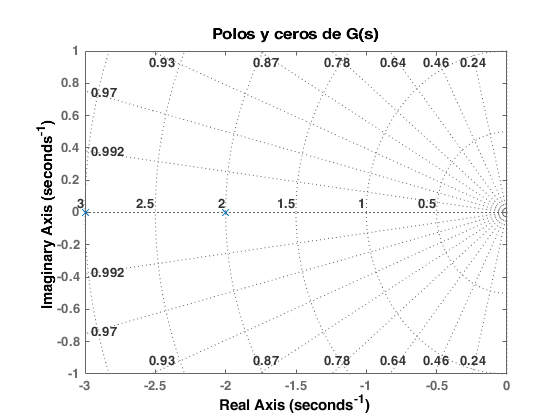

pzmap(G)
title('Polos y ceros de G(s)')
grid

El diagrama anterior corresponde a la función de transferencia $G\left(s\right)$.

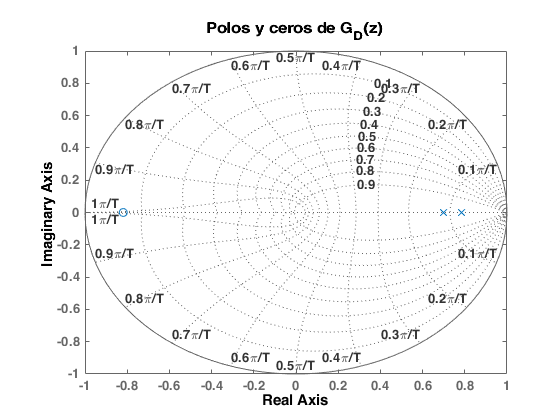

pzmap(Gd)
title('Polos y ceros de G_D(z)')
grid

El diagrama anterior corresponde a la función de transferencia $G_D \left(z\right)$.

pole(Gd)

ans =     0.7866
    0.6977


zero(Gd)

ans = -0.8187

Si para la función de transferencia discretizada se multiplica por 10 el período de muestreo, se obtiene la siguiente expresión:

Gd1 = c2d(G,10*Tm,'zoh')

Gd1 =
 
     1.3042 (z+0.1303)
  -----------------------
  (z-0.09072) (z-0.02732)
 
Sample time: 1.2 seconds
Discrete-time zero/pole/gain model.



Cuyo diagrama de polos y ceros es el siguiente:

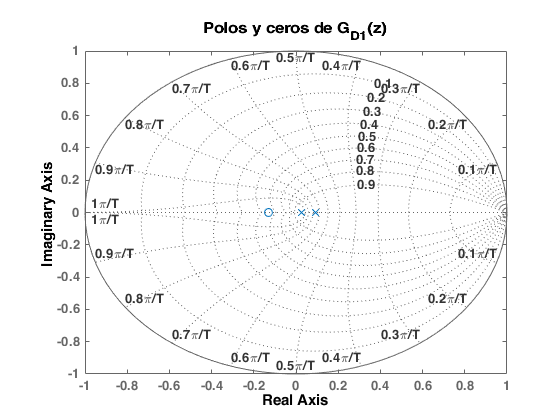

pzmap(Gd1)
title('Polos y ceros de G_{D1}(z)')
grid

Hay un efecto evidente al incrementar el período de muestreo, y es que los polos y ceros del sistema se acercan más al origen.

Ahora, se obtienen las respuestas a una entrada escalón unitario para el sistema $G\left(s\right)$ y para $G_D \left(s\right)$.

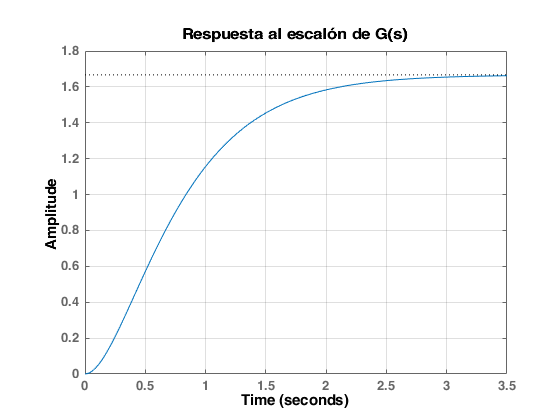

step(G)
title('Respuesta al escalón de G(s)')
grid

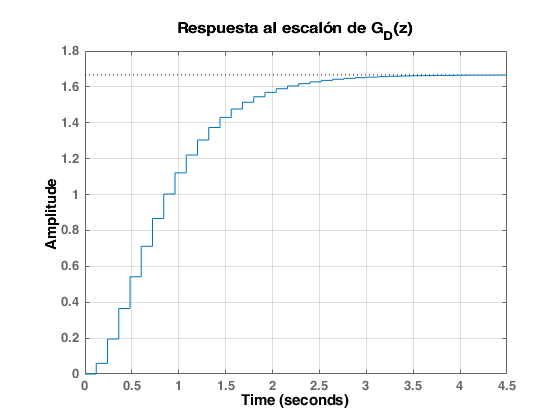

step(Gd)
title('Respuesta al escalón de G_D(z)')
grid

Una vez obtenidas las respuestas al escalón unitario del sistema es posible ver que estos sistemas son ambos estables, es decir, que la salida tiende en el infinito a acercarse a un cierto valor estable. Para comprobar por última vez esto, se llama al comando ´stepinfo()´.

stepinfo(G)

ans = struct with fields:
        RiseTime: 1.4130
    SettlingTime: 2.4766
     SettlingMin: 1.5013
     SettlingMax: 1.6654
       Overshoot: 0
      Undershoot: 0
            Peak: 1.6654
        PeakTime: 4.1216


stepinfo(Gd)

ans = struct with fields:
        RiseTime: 1.4400
    SettlingTime: 2.5200
     SettlingMin: 1.5146
     SettlingMax: 1.6667
       Overshoot: 0
      Undershoot: 0
            Peak: 1.6667
        PeakTime: 9.4800


Ahora, para el sistema discreto, se pide obtener:

- Tipo de sistema: en este caso el sistema es de tipo 0, ya que no tiene polos en el origen.

- Constante de error $K_P$

- Error ante una entrada del tipo rampa.

Para los últimos dos puntos, se procede a escribir el siguiente código.

Kp = dcgain(Gd)

Kp = 1.6667

Ahora, se comprueba la existencia del error en estado estable para un sistema en donde se cierre el lazo, teniendo como función de transferencia referencia a $G_D \left(s\right)$.

F = feedback(Gd,1)

F =
 
    0.059115 (z+0.8187)
  -----------------------
  (z^2 - 1.425z + 0.5972)
 
Sample time: 0.12 seconds
Discrete-time zero/pole/gain model.



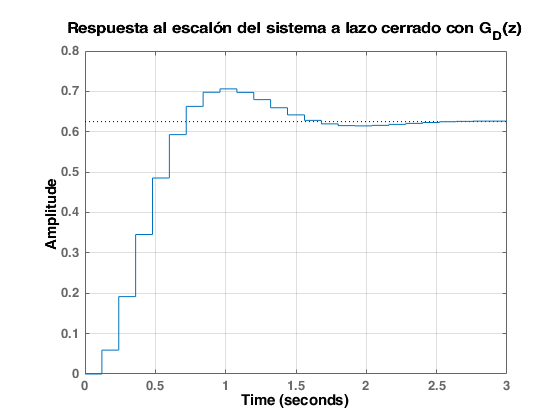

step(F)
title('Respuesta al escalón del sistema a lazo cerrado con G_D(z)')
grid

El error en estado estable para un sistema del tipo 0 se obtiene de la siguiente forma:

ess = 1/(Kp+1)

ess = 0.3750

Valor que predice un valor en estado estable definido como a continuación:

Fss = (1-ess)

Fss = 0.6250

Que se comprueba mediante el dcgain().

dcgain(F)

ans = 0.6250

Ahora, teniendo en cuenta que el sistema es de tipo 0, se debería predecir que el error en estado estable para una entrada del tipo rampa tiende al infinito. Es decir, que la salida para esa entrada diverge, solo resta comprobarlo mediante la simulación pertinente.

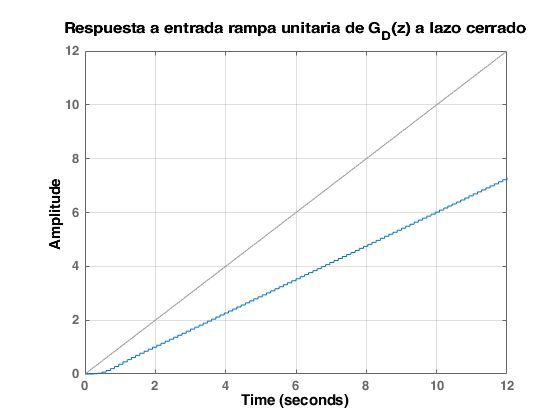

t = 0:Tm:100*Tm;
lsim(F,t,t)
title('Respuesta a entrada rampa unitaria de G_D(z) a lazo cerrado')
grid

A continuación, se obtienen los lugares de raíces de los tres sistemas en cuestión desarrollados hasta ahora. 

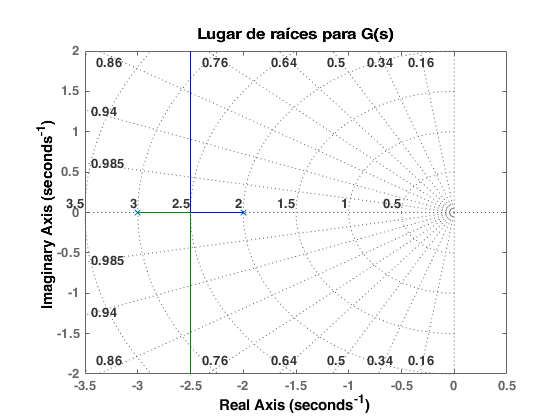

rlocus(G)
title('Lugar de raíces para G(s)')
grid

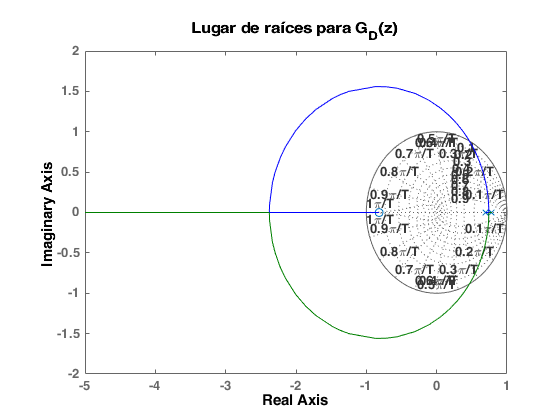

rlocus(Gd)
title('Lugar de raíces para G_D(z)')
grid

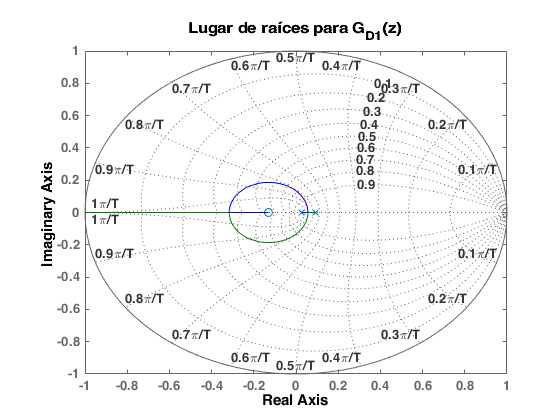

rlocus(Gd1)
title('Lugar de raíces para G_{D1}(z)')
grid

Para analizar la estabilidad relativa del sistema al aumentar el período de muestreo:

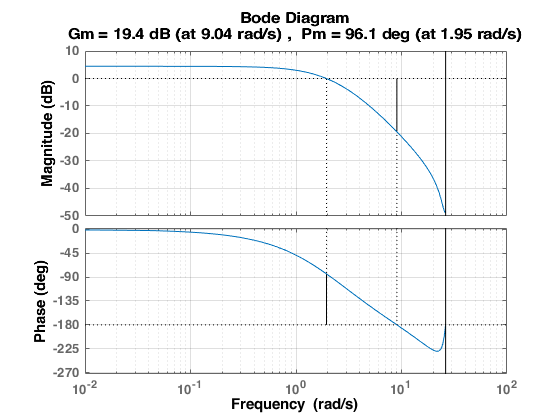

margin(Gd)
grid

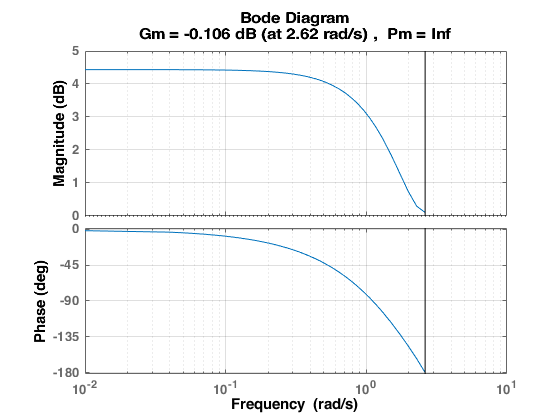

margin(Gd1)
grid

Se aprecia la reducción de la estabilidad relativa del sistema en cuestión al aumentar el período de muestreo. Esto puede verse desde otro punto de vista, es decir, al disminuir el período de muestreo, el sistema se acerca más uno continuo, que, en este caso es el original.